clear
clf

load('data/gauntlet_scans.mat')
warning('off','all')

r = r_all(:,1);
theta = theta_all(:,1);

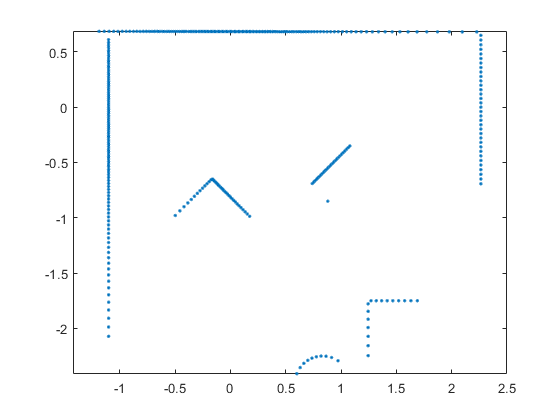

r_clean_index = find((r ~= 0) & (r < 3));
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(theta_clean, r_clean);
points = [x y];
clf
plot(x, y, '.')
axis equal

% find lines
d = 0.01

d = 0.0100

n = 500

n = 500

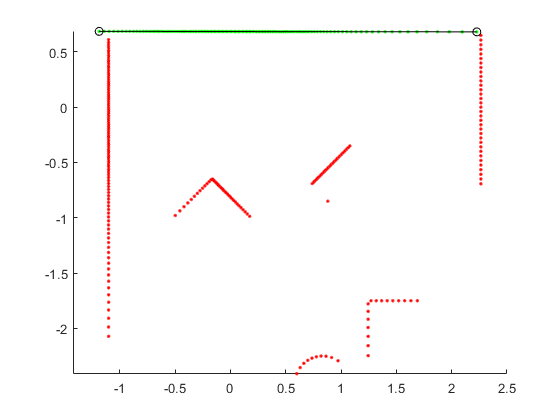

[endpoints_wall1, inliers_wall1, outliers_wall1, m, b] = ransac_line_fit(points, d, n, 0, 1);

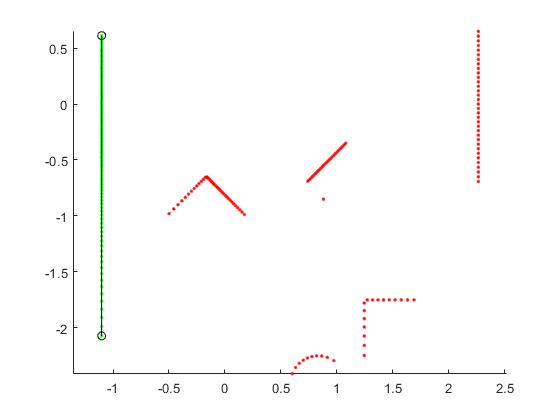

[endpoints_wall2, inliers_wall2, outliers_wall2, m, b] = ransac_line_fit(outliers_wall1, d, n, 0, 1);

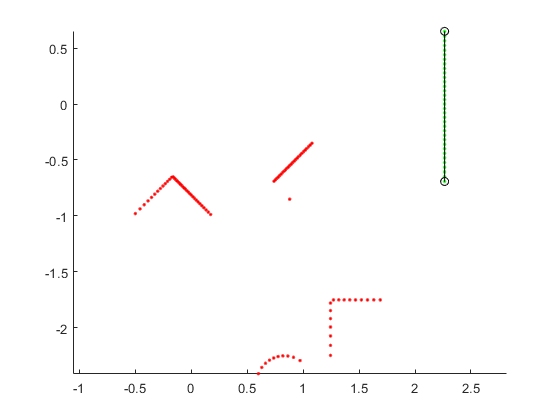

[endpoints_wall3, inliers_wall3, outliers_wall3, m, b] = ransac_line_fit(outliers_wall2, d, n, 0, 1);

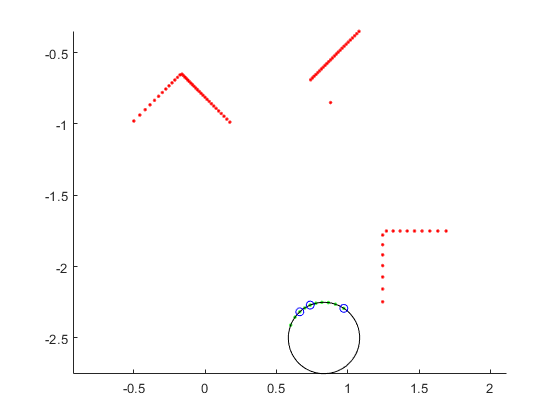

d = 0.01;
n = 5000;
r_max = 0.3;
[endpoints_circle, inliers_circle, outliers_circle, near_matches_circle, center, radius] = ransac_circle_fit(outliers_wall3, r_max, d, n, 1);

remainders = outliers_circle;

d = 0.01

d = 0.0100

n = 1000

n = 1000


endpointsx = [];
endpointsy = [];

while length(remainders) >= 3
    [endpoints, inliers, remainders, m, b] = ransac_line_fit(remainders, d, n, 1, 0);
    endpointsx = [endpointsx; endpoints(:,1)'];
    endpointsy = [endpointsy; endpoints(:,2)'];
end

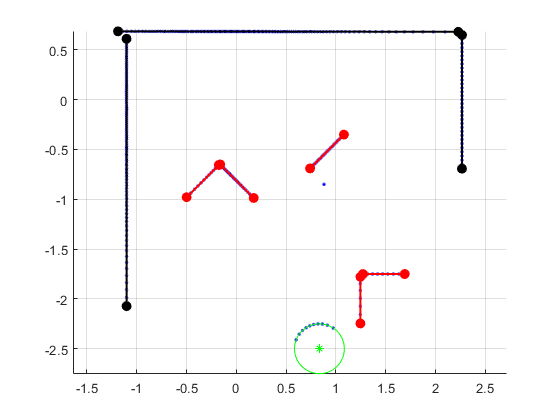

clf
hold on

% plot points
plot(x, y, 'b.')

% plot circle
plot_circle(center, radius, 'g-')
plot(center(1), center(2), 'g*')

% plot walls
plot(endpoints_wall1(:,1), endpoints_wall1(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall2(:,1), endpoints_wall2(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
plot(endpoints_wall3(:,1), endpoints_wall3(:,2), 'ko-', 'MarkerFaceColor', 'k', 'LineWidth', 1.5);

for i=1:length(endpointsx)
    plot(endpointsx(i,:), endpointsy(i,:), 'ro-', 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
end

grid on
axis equal